**BME 2740: Modeling and Simulation**

**Fall 2025 MATLAB Project **

**Students: Micaela Lopez Krol, Maria Agostina Nobo, Nicole Reboredo**

## A Model of the Cardiovascular System 

Build a compartmental model of the systemic arteries, left heart, and full heart (left & right heart, systemic & pulmonary arteries & veins) using the parameter set in the provided slides (“How to Create a Computational Model - A Focus on the Heart”). Simulate at least 25 heart beats and produce a series of plots of volumes, pressures, and flows for each compartment across time. Answer every question in the “Questions to Answer” PDF: Each answer must be complete, justified, and explained from both physiological and modeling perspectives. 

### Systemic Arteries Model

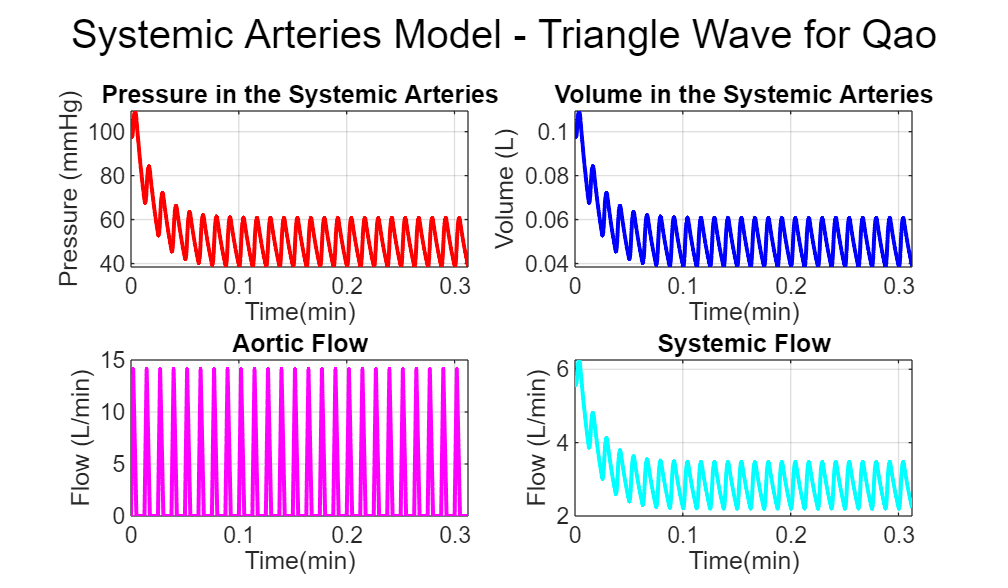

clear;clc;close all 

function Q=Qtriangwave(t,Qmax,T,ts,tmax)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 

% Initial Parameters
Psa=100; % Initial Condition for pressure in systemic arteries  (mmHg) 
Rs=17.5; % Resistance of the systemic circuit (mmHg/(L/min)) 
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
Qmax=14.14;  % Max flow rate through aorta during systole (L/min) 
Csa=0.001; % Compliance constant for systemic arteries (L/mmHg) 
% Csa was fiddled with to achieve Psa of 120/80 mmHg 
dt=0.0001; % Time step (min) 
t=0:dt:25*T;  % Vectorized time (min) 
Vsa=1; % Initial Condition for volume in the systemic arteries (L)

%% Solve Diff Eq 
for k=1:length(t)-1 
    QAo(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Flow rate at any given point in time 
    Psa(k+1)=Psa(k)+dt*(QAo(k)-Psa(k)/Rs)/Csa;  % Pressure at any given point in time 
end 

% Systemic Flow (Qs)
Qs=Psa/Rs;

% Volume in Systemic Arteries
Vsa=Csa*Psa;

% Plotting
figure('Position',[100 100 1200 700]);
sgtitle('Systemic Arteries Model - Triangle Wave for Qao');

subplot(2,2,1);
plot(t,Psa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');

subplot(2,2,2);
plot(t,Vsa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');

subplot(2,2,3);
plot(t(1:end-1),QAo,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

subplot(2,2,4);
plot(t,Qs,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Systemic Flow');

### Left Heart Model

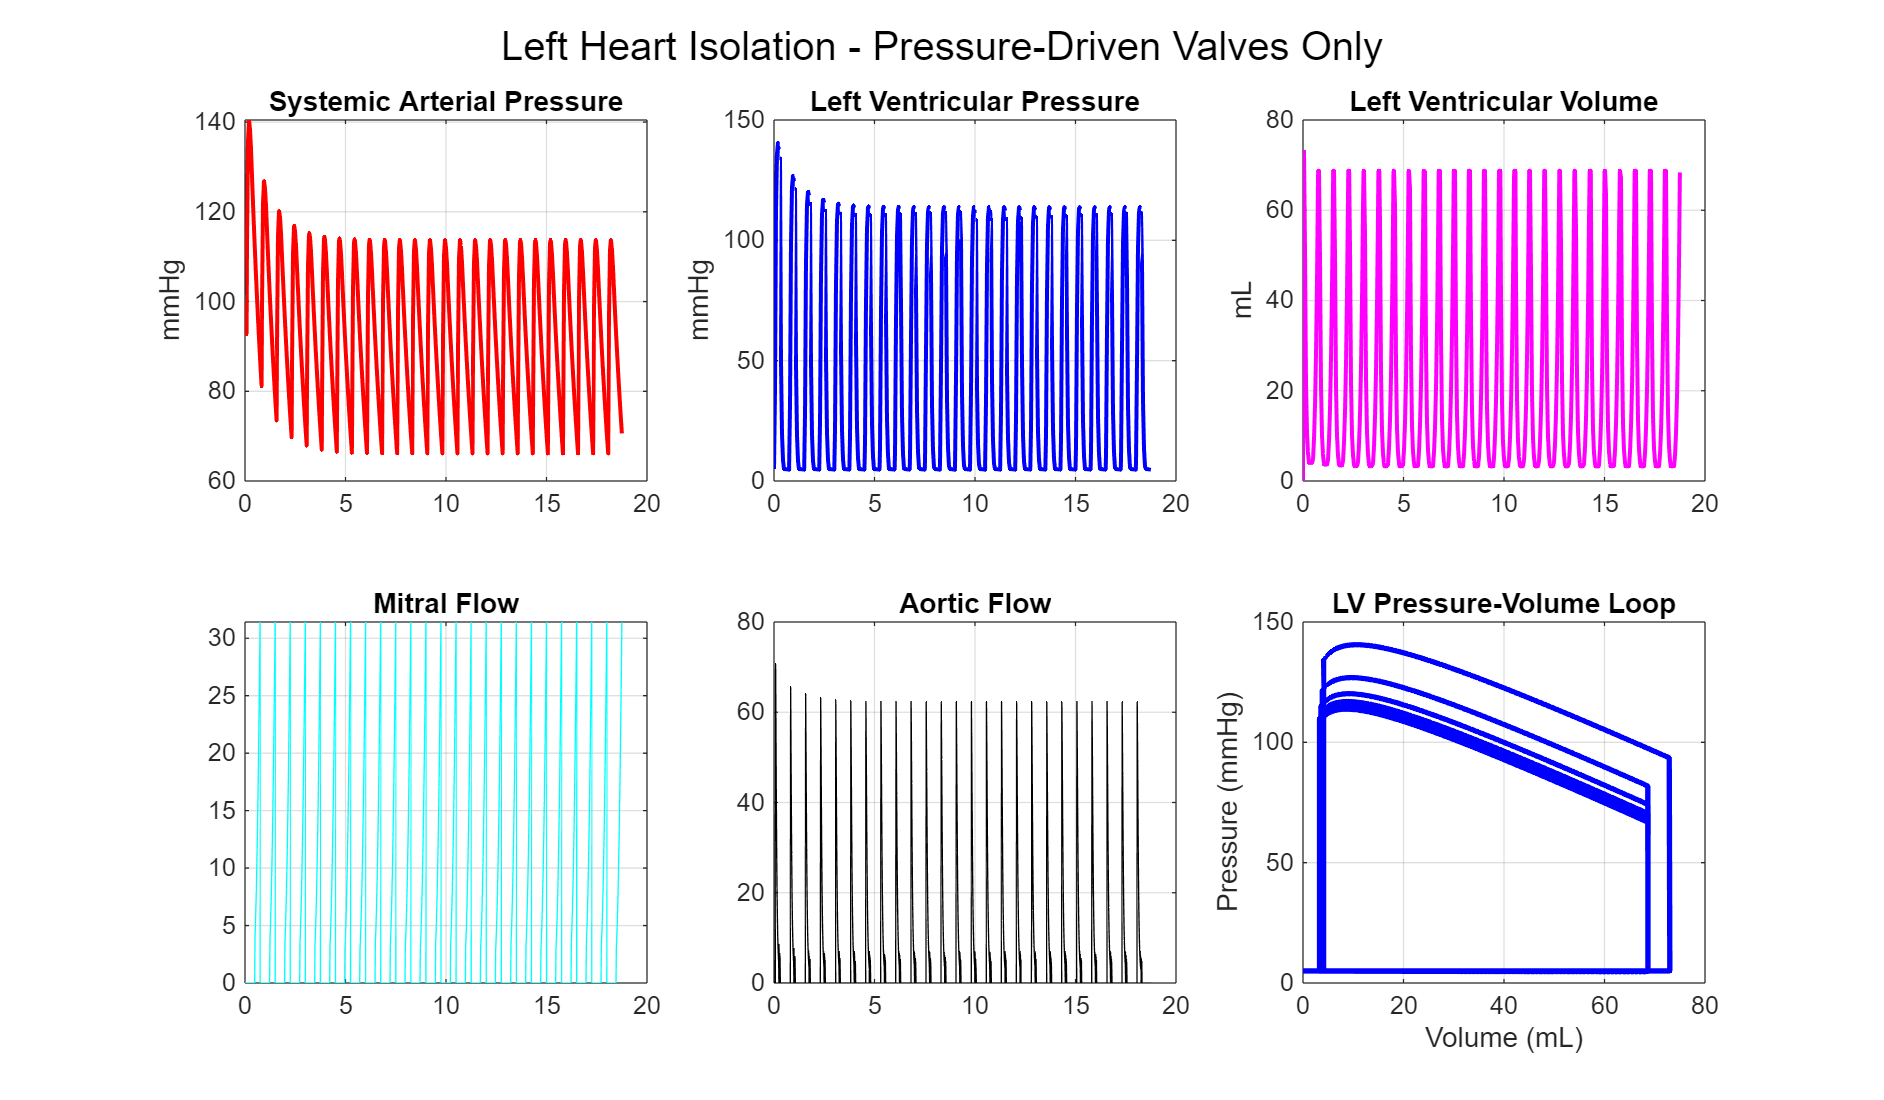

clear; clc; close all;

% PARAMETERS (Slide 37)
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-6; % Time step (must be small!)
t = 0:dt:25*T; % Simulate 25+ beats

tauS = 0.0025; % Systolic time constant
tauD = 0.0075; % Diastolic time constant
CLVS = 0.00003; % LV systolic compliance (L/mmHg)
CLVD = 0.0146; % LV diastolic compliance

Rmi = 0.01; % Mitral resistance
Rao = 0.01; % Aortic resistance
Rs  = 17.5; % Systemic resistance
Csa = 0.001; % Systemic arterial compliance
Ppv = 5; % Constant pulmonary venous pressure (left atrial proxy)

% INITIAL CONDITIONS
Psa(1) = 100;
Plv(1) = 5;

% PREALLOCATE
Psa = zeros(size(t)); Psa(1) = 100;
Plv = zeros(size(t)); Plv(1) = 5;
Vlv = zeros(size(t));

% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down); 

CLV = @(t) compute_dynamic_compliance(t, T, ts, tauS, tauD, CLVS, CLVD);

function C = compute_dynamic_compliance(t, T, ts, tauS, tauD, Csystolic, Cdiastolic)
    % slide 30 eq
    tc = mod(t, T); % Time within cardiac cycle
    
    % Precompute denominators
    denom_systole = 1 - exp(-ts/tauS);
    denom_diastole = 1 - exp(-(T-ts)/tauD);
    
    % Systole phase (0 ≤ tc ≤ ts)
    in_systole = tc <= ts;
    e_sys = (1 - exp(-tc(in_systole)/tauS))./ denom_systole;
    C_sys = Cdiastolic * (Csystolic / Cdiastolic).^e_sys;
    
    % Diastole phase (ts < tc < T)
    in_diastole = tc > ts;
    e_dia = (1 - exp(-(tc(in_diastole) - ts)/tauD)) ./ denom_diastole;
    C_dia = Csystolic * (Cdiastolic / Csystolic).^e_dia;
    
    % Combine results
    C = zeros(size(t));
    C(in_systole) = C_sys;
    C(in_diastole) = C_dia;
end

% MAIN LOOP - LEFT HEART ISOLATION
for k = 1:length(t)-1
    % Current and next compliance
    Clv_now = CLV(t(k));
    Clv_next = CLV(t(k+1));
    
    % PRESSURE-DRIVEN VALVES ONLY
    S_mi = valve_open(Ppv, Plv(k)); % Mitral: open if P_LA > P_LV
    S_ao = valve_open(Plv(k), Psa(k)); % Aortic: open if P_LV > P_sa
    
    % Flows
    Qmi = S_mi * (Ppv - Plv(k)) / Rmi;
    Qao = S_ao * (Plv(k) - Psa(k)) / Rao;
    Qs  = Psa(k) / Rs;
    
    % Systemic arteries (normal ODE)
    dPsa_dt = (Qao - Qs) / Csa;
    Psa(k+1) = Psa(k) + dt * dPsa_dt;
    
    % Left ventricle with time-varying compliance (Slide 28)
    Plv(k+1) = (Plv(k) * Clv_now + dt * (Qmi - Qao)) / Clv_next;
    
    % Volume from pressure
    Vlv(k+1) = Plv(k+1) * Clv_next;
end

% PLOT (25 Beats)
t_sec = t * 60;
idx = 1:round(25*T/dt);

figure('Position',[100 100 1200 700]);
sgtitle('Left Heart Isolation - Pressure-Driven Valves Only');

subplot(2,3,1); plot(t_sec(idx), Psa(idx), 'r', 'LineWidth',1.5); grid on;
title('Systemic Arterial Pressure'); ylabel('mmHg');

subplot(2,3,2); plot(t_sec(idx), Plv(idx), 'b', 'LineWidth',1.5); grid on;
title('Left Ventricular Pressure'); ylabel('mmHg');

subplot(2,3,3); plot(t_sec(idx), Vlv(idx)*1000, 'm', 'LineWidth',1.5); grid on;
title('Left Ventricular Volume'); ylabel('mL');

subplot(2,3,4); plot(t_sec(idx), valve_open(Ppv, Plv(idx)).* (Ppv - Plv(idx))/Rmi, 'c'); grid on;
title('Mitral Flow');

subplot(2,3,5); plot(t_sec(idx), valve_open(Plv(idx), Psa(idx)).* (Plv(idx) - Psa(idx))/Rao, 'k'); grid on;
title('Aortic Flow');

subplot(2,3,6); plot(Vlv(idx)*1000, Plv(idx), 'b', 'LineWidth',2); grid on;
title('LV Pressure-Volume Loop'); xlabel('Volume (mL)'); ylabel('Pressure (mmHg)');

% RESULTS
fprintf('Left Heart Model - Steady State:\n');

Left Heart Model - Steady State:


fprintf('Mean Arterial Pressure: %.1f mmHg\n', mean(Psa(end-5000:end)));

Mean Arterial Pressure: 81.7 mmHg


fprintf('LV Peak Pressure:%.1f mmHg\n', max(Plv(end-5000:end)));

LV Peak Pressure:6.8 mmHg


fprintf('Stroke Volume: %.1f mL\n',   max(Vlv(end-5000:end)*1000) - min(Vlv(end-5000:end)*1000));

Stroke Volume: 65.2 mL


fprintf('Cardiac Output: %.2f L/min\n', mean(valve_open(Plv, Psa) .* (Plv - Psa)/Rao));

Cardiac Output: 5.25 L/min


### Right Heart Model

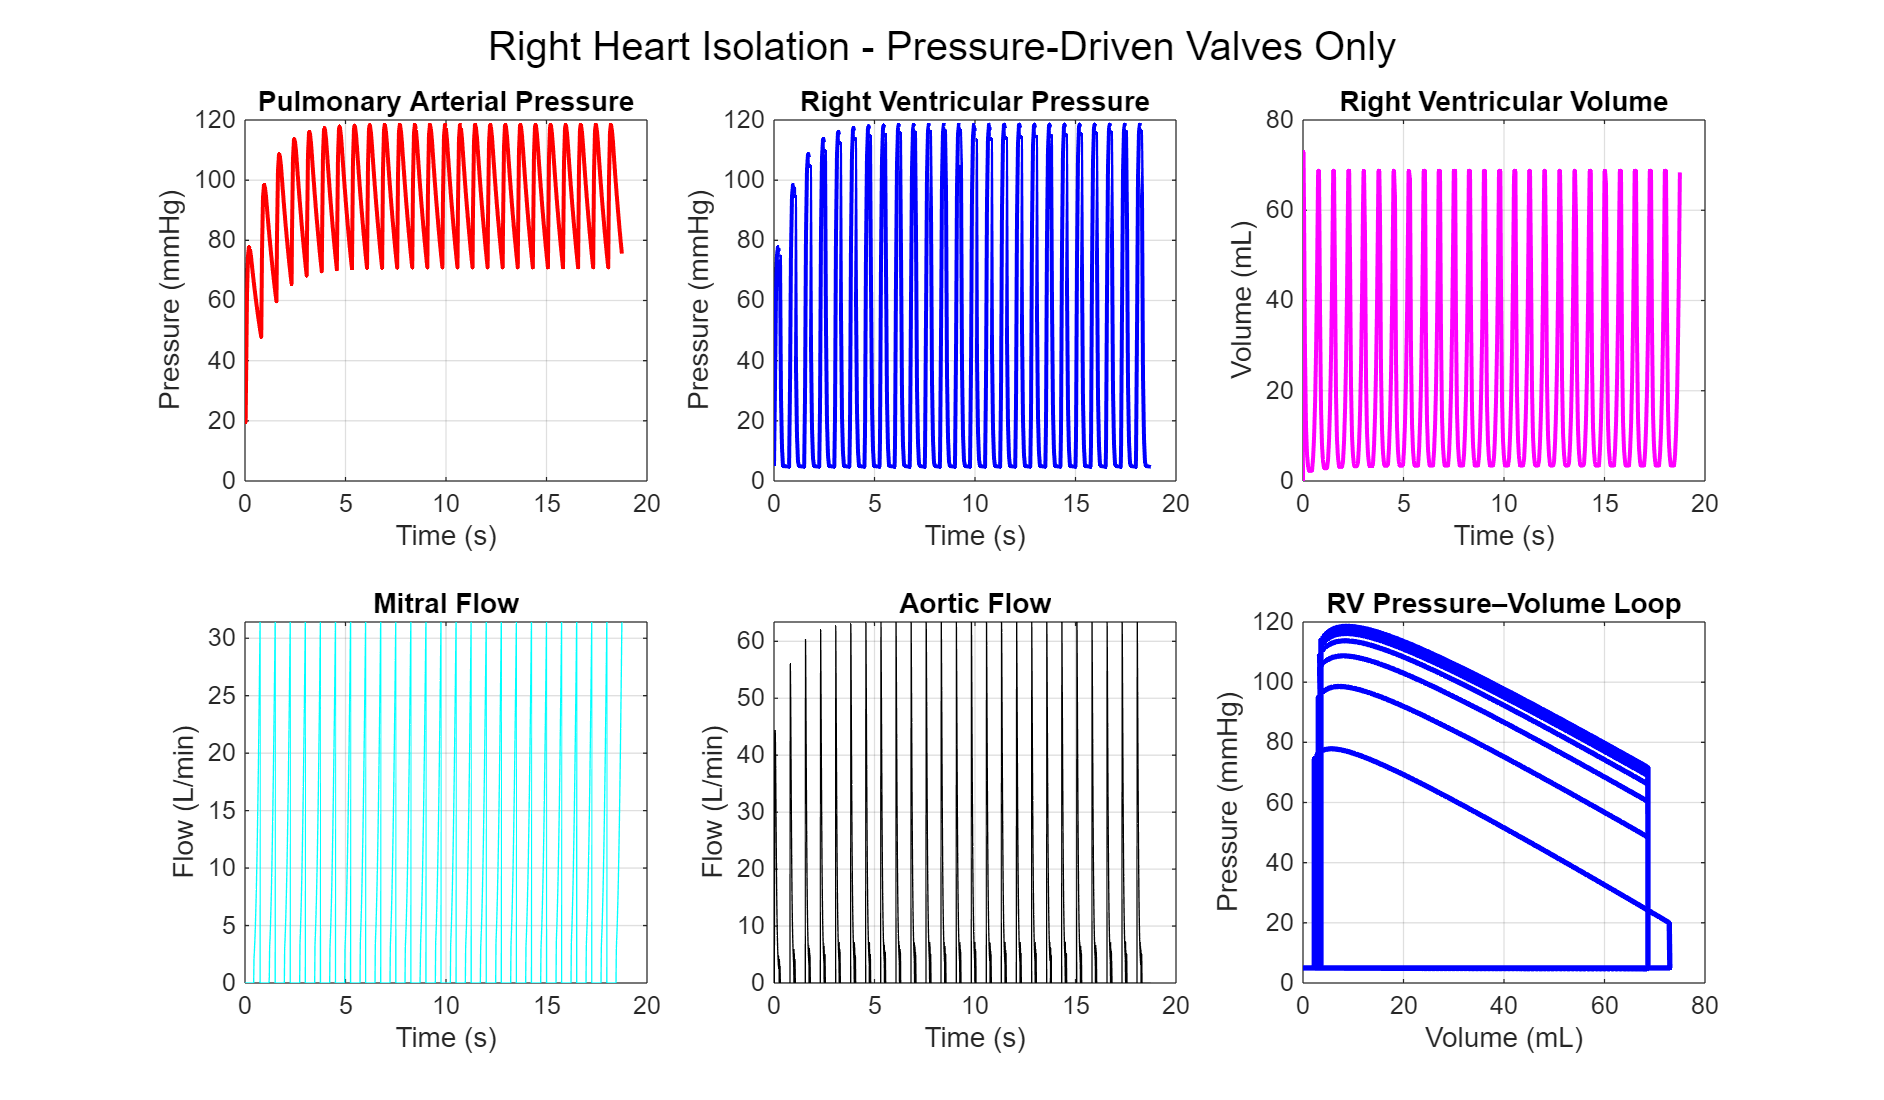

%RIGHT HEART 
clear; close all; clc

% PARAMETERS (Slide 37). Same as left heart model 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-6; % Time step (must be small!)
t = 0:dt:25*T; % Simulate 25+ beats

tauS=0.0025; % Systolic time constant
tauD=0.0075; % Diastolic time constant
CRVS=0.00003; % LV systolic compliance (L/mmHg)
CRVD=0.0146; % LV diastolic compliance

Rti=0.01; % Mitral resistance
Rpo=0.01; % Aortic resistance
Rp= 17.5; % Systemic resistance
Cpa=0.001; % Systemic arterial compliance
Ppv=5; % Constant pulmonary venous pressure (right atrial proxy)
Psv=5; %constant systemic venous pressure (right atrial)

% INITIAL CONDITIONS
Psa(1)=100;   
Plv(1)=5;    

Ppa=zeros(size(t)); Ppa(1)=20;   % Pulmonary arterial pressure
Prv=zeros(size(t)); Prv(1)=5;    % Right ventricular pressure
Vrv=zeros(size(t));              % Right ventricular volume (L)

%% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down);

% Time-varying RV compliance (same function as LV, new parameters)
CRV=@(tt) compute_dynamic_compliance(tt, T, ts, tauS, tauD, CRVS, CRVD);

%% MAIN LOOP – RIGHT HEART ISOLATION
for k = 1:length(t)-1
    
    % Current and next compliance
    Crv_now  = CRV(t(k));
    Crv_next = CRV(t(k+1));
    
    % PRESSURE-DRIVEN VALVES
    S_ti = valve_open(Psv,   Prv(k));   % Tricuspid: open if P_sv > P_RV
    S_po = valve_open(Prv(k), Ppa(k));  % Pulmonic:  open if P_RV > P_pa
    
    % FLOWS (L/min)
    Qti = S_ti * (Psv   - Prv(k)) / Rti;        % Tricuspid inflow
    Qpo = S_po * (Prv(k) - Ppa(k)) / Rpo;       % Pulmonic outflow
    Qp  = (Ppa(k) - Ppv) / Rp;                 % Pulmonary vascular flow
    
    % PULMONARY ARTERIES (ODE)
    dPpa_dt   = (Qpo - Qp) / Cpa;
    Ppa(k+1)  = Ppa(k) + dt * dPpa_dt;
    
    % RIGHT VENTRICLE WITH TIME-VARYING COMPLIANCE
    Prv(k+1)  = (Prv(k) * Crv_now + dt * (Qti - Qpo)) / Crv_next;
    
    % VOLUME FROM PRESSURE
    Vrv(k+1)  = Prv(k+1) * Crv_next;
end

%% PLOTS (25 BEATS)
t_sec = t * 60;                 % convert min -> s
idx   = 1:round(25*T/dt);       % indices for 25 beats

figure('Position',[100 100 1200 700]);
sgtitle('Right Heart Isolation - Pressure-Driven Valves Only');

% Pulmonary arterial pressure
subplot(2,3,1);
plot(t_sec(idx), Ppa(idx), 'r', 'LineWidth', 1.5); grid on;
title('Pulmonary Arterial Pressure'); ylabel('Pressure (mmHg)');
xlabel('Time (s)');

% Right ventricular pressure
subplot(2,3,2);
plot(t_sec(idx), Prv(idx), 'b', 'LineWidth', 1.5); grid on;
title('Right Ventricular Pressure'); ylabel('Pressure (mmHg)');
xlabel('Time (s)');

% Right ventricular volume
subplot(2,3,3);
plot(t_sec(idx), Vrv(idx)*1000, 'm', 'LineWidth', 1.5); grid on;
title('Right Ventricular Volume'); ylabel('Volume (mL)');
xlabel('Time (s)');

% Mitral flow
subplot(2,3,4);
plot(t_sec(idx), valve_open(Psv, Prv(idx)).*(Psv - Prv(idx))/Rti, 'c'); grid on;
title('Mitral Flow'); ylabel('Flow (L/min)');
xlabel('Time (s)');

% Pulmonic flow
subplot(2,3,5);
plot(t_sec(idx), valve_open(Prv(idx), Ppa(idx)).*(Prv(idx) - Ppa(idx))/Rpo, 'k'); grid on;
title('Aortic Flow'); ylabel('Flow (L/min)');
xlabel('Time (s)');

% RV pressure-volume loop
subplot(2,3,6);
plot(Vrv(idx)*1000, Prv(idx), 'b', 'LineWidth', 2); grid on;
title('RV Pressure–Volume Loop');
xlabel('Volume (mL)'); ylabel('Pressure (mmHg)');

%% Displaying results 
fprintf('Right Heart Model - Steady State:\n\n');

Right Heart Model - Steady State:



fprintf('Mean Pulmonary Arterial Pressure: %.1f mmHg\n', mean(Ppa(end-5000:end)));

Mean Pulmonary Arterial Pressure: 86.7 mmHg


fprintf('RV Peak Pressure: %.1f mmHg\n', max(Prv(end-5000:end)));

RV Peak Pressure: 7.1 mmHg


stroke_vol = max(Vrv(end-5000:end))*1000 - min(Vrv(end-5000:end))*1000;
fprintf('Stroke Volume: %.1f mL\n', stroke_vol);

Stroke Volume: 65.0 mL


% Cardiac output based on pulmonic flow
Qpo_all = valve_open(Prv, Ppa) .* (Prv - Ppa) / Rpo;
fprintf('Cardiac Output: %.2f L/min\n', mean(Qpo_all(1:end)));

Cardiac Output: 5.25 L/min


### Pulmonary Arteries Model

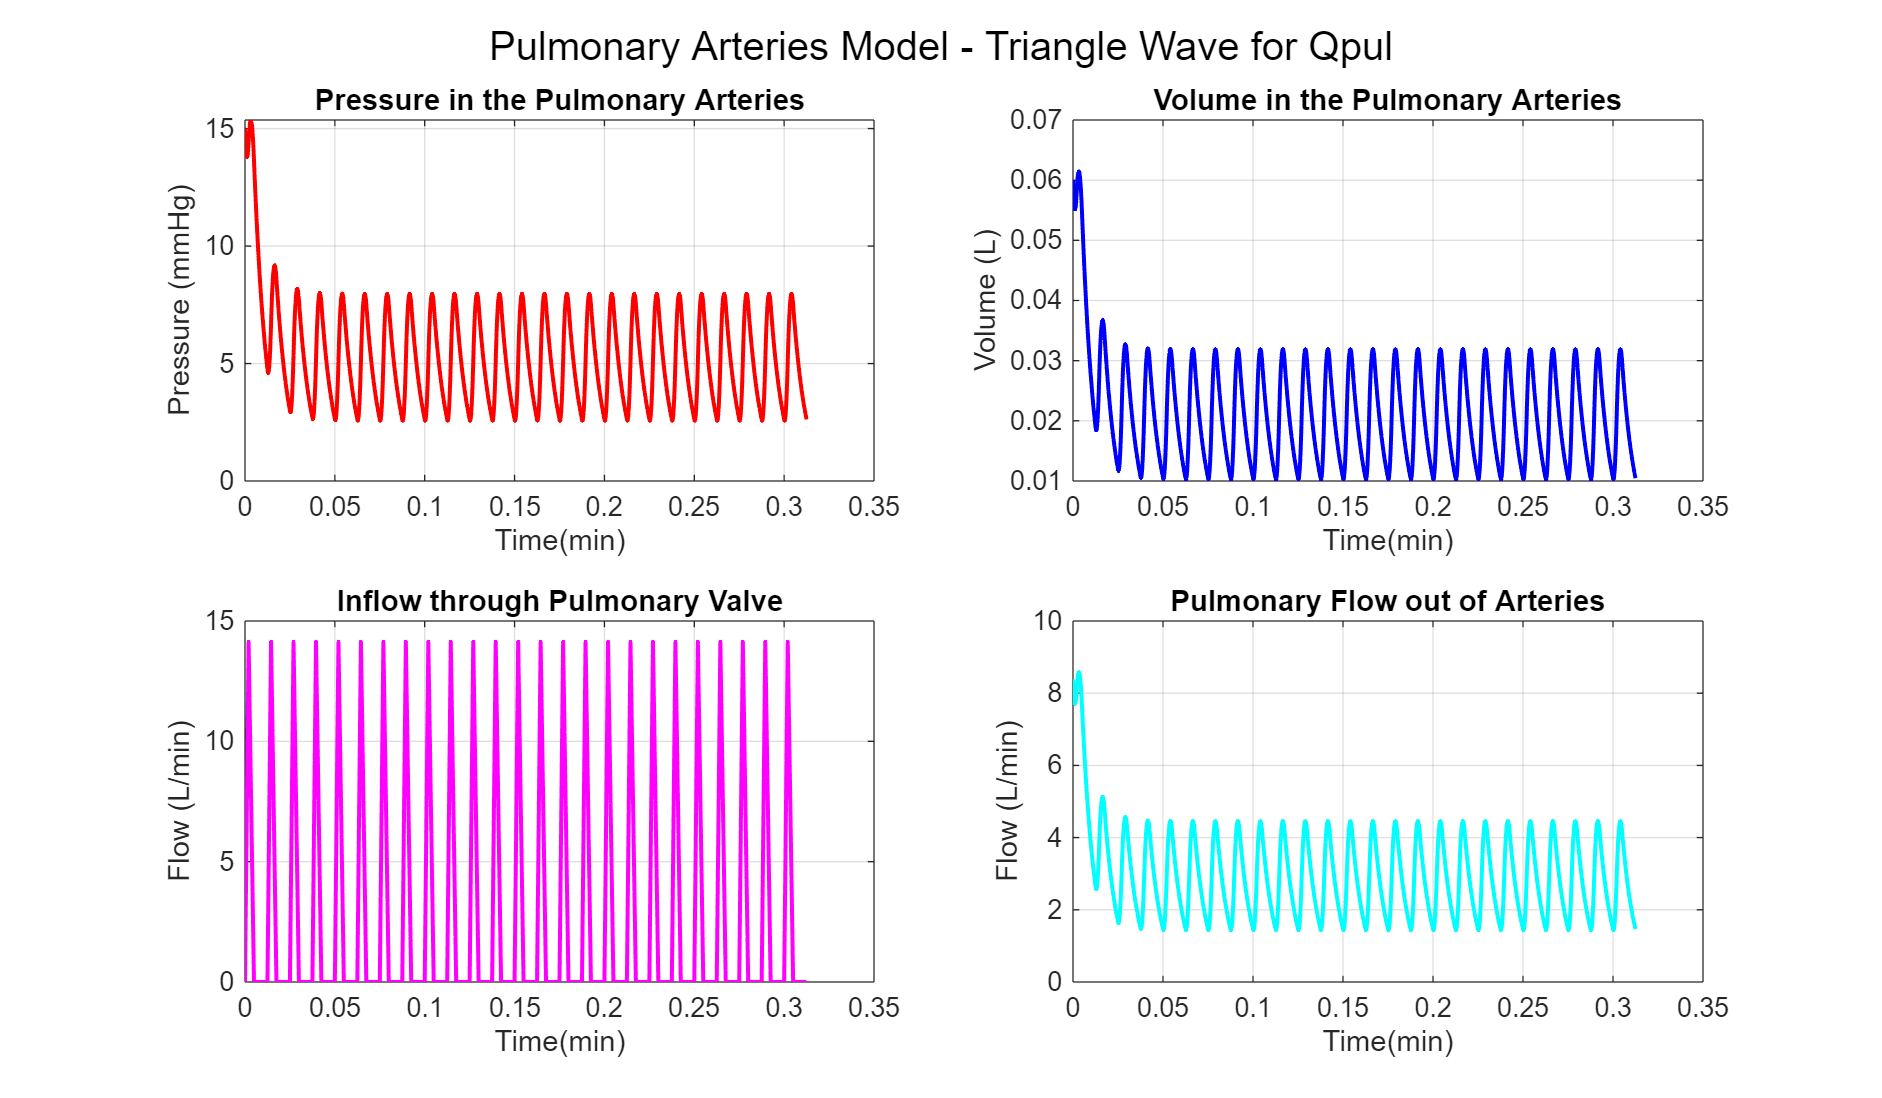

clear;clc;close all 

% Initial Parameters
Ppa=15; % Initial Condition for pressure in pulmonary arteries (mmHg) 
Rp=1.79; % Resistance of the pulmonary circuit (mmHg/(L/min)) 
T=0.0125; % Time for 1 heart beat (min) 
ts=0.0050;  % Time for systole (min) 
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave 
Qmax=14.14;  % Max flow rate through pulmonary valve during systole (L/min) 
Cpa=0.004; % Compliance constant for pulmonary arteries (L/mmHg) 
dt=0.0001; % Time step (min) 
t=0:dt:25*T;  % Vectorized time (min) 
Vpa=0.1; % Initial Condition for volume in the pulmonary arteries (L)

%% Solve Diff Eq 
for k=1:length(t)-1 
    Qpul(k)=Qtriangwave(t(k),Qmax,T,ts,tmax);  % Flow rate at any given point in time
    Ppa(k+1)=Ppa(k)+dt*(Qpul(k)-Ppa(k)/Rp)/Cpa;  % Pressure at any given point in time 
end 

% Pulmonary Flow (Qp)
Qp=Ppa/Rp; % Assuming Ppv << Ppa, otherwise Qp = (Ppa-Ppv)/Rp

% Volume in Pulmonary Arteries
Vpa=Cpa*Ppa;

% Plotting
figure('Position',[100 100 1200 700]);
sgtitle('Pulmonary Arteries Model - Triangle Wave for Qpul');

subplot(2,2,1);
plot(t,Ppa, 'r','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Pulmonary Arteries');

subplot(2,2,2);
plot(t,Vpa,'b','LineWidth',1.5);
grid on
xlabel('Time(min)');
ylabel('Volume (L)');
title('Volume in the Pulmonary Arteries');

subplot(2,2,3);
plot(t(1:end-1),Qpul,'m','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Inflow through Pulmonary Valve');

subplot(2,2,4);
plot(t,Qp,'c','LineWidth',1.5); 
grid on
xlabel('Time(min)');
ylabel('Flow (L/min)');
title('Pulmonary Flow out of Arteries');

### Systemic Veins Model

### Pulmonary Veins Model

### Full Heart Model

Full heart using this 6 diff eq's

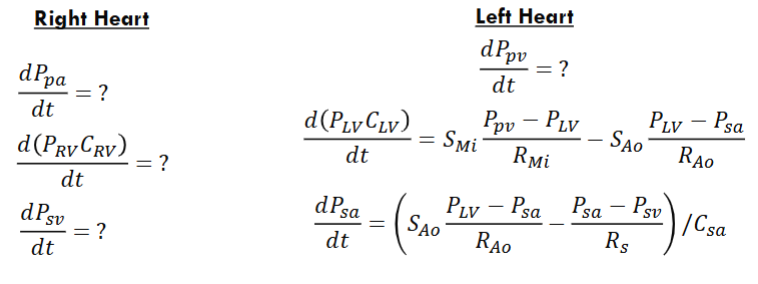

Full heart model (Left+Right+Artery+Veins) 